# Demo: using FEMA for fitting linear mixed-effects modeling with unstructured covariance

This demo showcases using `FEMA_fit` for fitting linear mixed-effects models while allowing for time-varying random effects (i.e., different covariance at different time points)

## Requirements

Please modify this paths to where you have downloaded the FEMA toolbox; if you already have FEMA on your MATLAB path, then this step is not required

addpath(genpath('/Applications/Projects/2025-11-28_FEMA-Demo/cmig_tools-main'))

## Simulating dataset

### Settings

% Different variance components
var_noise  = 0.1;
var_subj   = 0.3;
var_family = 0.2;
var_FFX    = 0.5;
var_RFX    = var_family + var_subj;

% Range for beta coefficients
betaLow   = -0.2;
betaHigh  = 0.2;

% How many X variables do we want?
nXvars = 50;

% Number of y variables
nyVars = 1;

% Total number of visits
numVisits = 5;

% Approximate total number of unique individuals
nIndividuals = 5000;

% Maximum number of individuals in a family
maxNumInFamily = 5;

% Maximum number of observations
maxObservations = 20000;

% Probability of repeated measurements existing
eventProb = [0.95, 0.7, 0.8, 0.6, 0.75];

% For age, mean and standard deviations (in days)
meanAges = [0, 60, 180, 240, 365];
stdAges  = [0, 10, 12,  14,  15];

% Max itertions for nearestSPD converge
maxIter = 100;

% Random effects
RandomEffects = {'F', 'S'};

%% Generate a large number of seeds
rng(202511305, 'twister');

### Simulate time-varying covariance matrices

% Generate covariance matrices
while true
    % Arbitrary covariance matrix - subject effect
    allVariances_subj   = rand(numVisits, 1);
    allCovariances_subj = randn((numVisits * (numVisits - 1))/2, 1);

    % Diagonal and off-diagonal locations
    locsDiagonal = 1:numVisits+1:numVisits^2;
    locsOffDiag  = find(tril(ones(numVisits), -1));

    % Put together as a full matrix
    varCovarMatrix_subj = zeros(numVisits);
    varCovarMatrix_subj(locsDiagonal) = allVariances_subj;
    varCovarMatrix_subj(locsOffDiag)  = allCovariances_subj;

    % Make symmetric, followed by semipositive definite
    varCovarMatrix_subj = tril(varCovarMatrix_subj, -1) + varCovarMatrix_subj.';
    [varCovarMatrix_subj, converge] = nearestSPD_timeout(varCovarMatrix_subj, maxIter);

    if ~converge
        continue;
    else
        break;
    end
end

while true
    % Arbitrary covariance matrix - family effect
    allVariances_family   = rand(numVisits, 1);
    allCovariances_family = randn((numVisits * (numVisits - 1))/2, 1);

    % Diagonal and off-diagonal locations
    locsDiagonal = 1:numVisits+1:numVisits^2;
    locsOffDiag  = find(tril(ones(numVisits), -1));

    % Put together as a full matrix
    varCovarMatrix_family = zeros(numVisits);
    varCovarMatrix_family(locsDiagonal) = allVariances_family;
    varCovarMatrix_family(locsOffDiag)  = allCovariances_family;

    % Make symmetric, followed by semipositive definite
    varCovarMatrix_family = tril(varCovarMatrix_family, -1) + varCovarMatrix_family.';
    [varCovarMatrix_family, converge] = nearestSPD_timeout(varCovarMatrix_family, maxIter);

    if ~converge
        continue;
    else
        break;
    end
end

### Create family structure

% Simulate IDs
% Generate individual IDs
iid_int = sort(repmat(1:nIndividuals, 1, numVisits));

% Generate family IDs
fid_int = ceil(iid_int / maxNumInFamily);

iid = cellstr([repmat('I', length(iid_int),1), dec2base(iid_int,10)]);
fid = cellstr([repmat('F', length(fid_int),1), dec2base(fid_int,10)]);
clear('iid_int'); clear('fid_int');

% Generate event IDs
allEvents = (1:numVisits)';
eid       = repmat(allEvents, nIndividuals, 1);

%% Now, annihilate vists
toKeep   = randperm(length(iid), maxObservations);
toDelete = setdiff(1:length(iid), toKeep);
eid(toDelete) = [];
iid(toDelete) = [];
fid(toDelete) = [];

% Additionally create timepoint variable
timepoint = eid;

%% Simulate age for each ID, each event
allIDs = unique(iid, 'stable');
agevec = zeros(length(iid), 1);
count  = 1;
for i = 1:length(allIDs)
    whichEvents = eid(strcmpi(iid, allIDs{i}));
    howMany     = length(whichEvents);
    agevec(count:count+howMany-1) = floor(stdAges(whichEvents) .* randn(1, 1) + meanAges(whichEvents));
    count = count + howMany;
end

%% Create clusterinfo - FSE
clusterinfo = FEMA_parse_family(iid, eid, fid, agevec, [], 'RandomEffects', {'F', 'S', 'E'});

03-Dec-2025 10:22:34 in FEMA_parse_family - Parsing family structure


## Simulate fixed effects and outcome

% Simulate fixed effects
knots = [meanAges, max(agevec)];
basisFunction = createBasisFunctions(agevec, knots, 'nsk', [], 'svd');
remX   = nXvars - (size(basisFunction, 2) + 1);
otherX = randn(length(iid),remX);

% Put all X variables together
X         = [ones(length(iid), 1), basisFunction, otherX];
colnames  = [{'Intercept'}, strrep(strcat({'Basis_'}, num2str((1:size(basisFunction,2))')), ' ', '')', strrep(strcat({'Other_'}, num2str((1:size(otherX,2))')), ' ', '')'];

eff_FFX   = betaLow + (betaHigh - betaLow) .* rand(nXvars, 1);
y_FFX     = X * eff_FFX;
locIC     = false(size(X,2),1);
locIC(1)  = true;

% Mean center and scale by standard deviation
std_FFX  = std(y_FFX);
mean_FFX = mean(y_FFX);

% Standardize FFX_y: both mean centering and standardizing
y_FFX = (y_FFX - mean_FFX)./ std_FFX;
y_FFX = sqrt(var_FFX)' .* y_FFX;

% Update effect sizes
mod_FFX            = eff_FFX;
mod_FFX(~locIC, :) = mod_FFX(~locIC,:) ./ std_FFX;
mod_FFX(locIC,  :) = (mod_FFX(locIC,:) - mean_FFX) ./ std_FFX;
mod_FFX            = sqrt(var_FFX)' .* mod_FFX;

%% Repeated measurements - same effect across subjects
y_RFX   = zeros(length(iid), nyVars);
for fi  = 1:length(clusterinfo)
    % Family effect
    [~, b]   = ismember(eid(clusterinfo{fi}.jvec_fam), allEvents);
    V_family = varCovarMatrix_family(b, b);
    tmp1     = sqrt(var_family/var_RFX) .* mvnrnd(zeros(length(clusterinfo{fi}.jvec_fam), 1), double(V_family) .* clusterinfo{fi}.V_F, nyVars)';

    % Subject effect
    V_subj  = varCovarMatrix_subj(b, b);
    tmp2    = sqrt(var_subj/var_RFX) .* mvnrnd(zeros(length(clusterinfo{fi}.jvec_fam), 1), double(V_subj) .* clusterinfo{fi}.V_S, nyVars)';

    % Put them together
    y_RFX(clusterinfo{fi}.jvec_fam,:) = sqrt(var_RFX) .* (tmp1 + tmp2);
end

% Noise
noise   = rand(length(iid),  nyVars);
noise   = (noise - mean(noise))./std(noise);
noise   = noise .* sqrt(var_noise)';

% Put phenotype together
ymat = y_RFX + y_FFX + noise;

## Estimation of unstructured covariance matrices

niter       = 1;
contrasts   = [];
nbins       = 20; % unstructured covariance does not currently use binning
GRM         = [];
[beta_hat,      beta_se,        zmat,        logpmat,              ...
 sig2tvec,      sig2mat,        Hessmat,     logLikvec,            ...
 beta_hat_perm, beta_se_perm,   zmat_perm,   sig2tvec_perm,        ...
 sig2mat_perm,  logLikvec_perm, binvec_save, nvec_bins,            ...
 tvec_bins,     FamilyStruct,   coeffCovar,  reusableVars] =       ...
 FEMA_fit(X, iid, eid, fid, agevec, ymat, niter, contrasts, nbins, ...
          GRM, 'RandomEffects', {'F', 'S', 'E'},                   ...
          'CovType', 'unstructured', 'returnReusable', true);

03-Dec-2025 10:22:35 in FEMA_fit - ***Start***
FEMA 3.0.0 (2025.09.17)
ModelSingularityIndex = 15.4618
03-Dec-2025 10:22:35 in FEMA_parse_family - Parsing family structure
Elapsed time is 0.549370 seconds.
03-Dec-2025 10:22:37 in FEMA_fit - size(M) = [404016 3]
03-Dec-2025 10:22:37 in FEMA_fit - Cov_MoM:
   1.0e-04 *

    0.0312   -0.0312   -0.0000
   -0.0312    0.1876   -0.1564
   -0.0000   -0.1564    0.6564

03-Dec-2025 10:22:37 in FEMA_fit - Mi*M:
    0.9965    0.0000   -0.0000
   -0.0000    0.9995    0.0000
    0.0000    0.0000    1.0001

03-Dec-2025 10:22:37 in FEMA_fit - ***Done*** (1.93 seconds)



## Examine unstructured covariance matrices

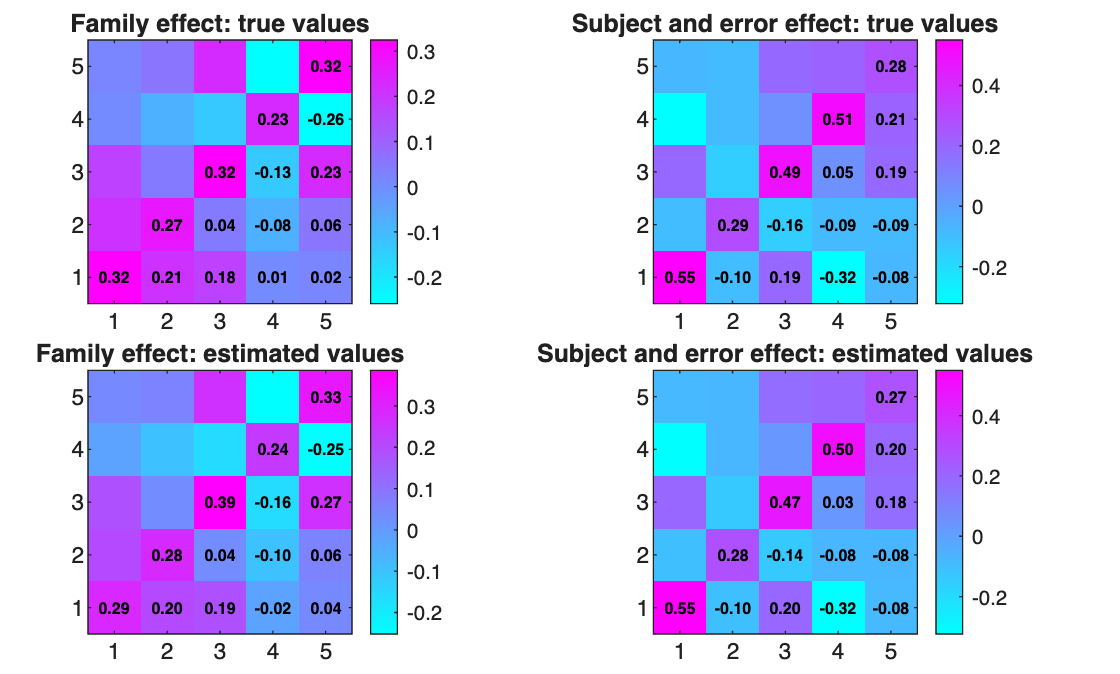

fig  = figure;
allH = tight_subplot(2, 2, [0.1 0.05], [0.06 0.06], [0.02 0.02]);

true_family  = varCovarMatrix_family .* var_family;
true_subject = varCovarMatrix_subj .* var_subj + eye(5) .* var_noise;
est_family   = sig2mat(:,:,1) .* sig2tvec;
est_subject  = sig2mat(:,:,2) .* sig2tvec;

% Family effect: ground truth
imagesc(allH(1), true_family);
axis(allH(1), 'image');
axis(allH(1), 'xy');
colormap(allH(1), 'cool');
colorbar(allH(1), 'eastoutside');
title(allH(1), 'Family effect: true values');

% Subject effect: ground truth
imagesc(allH(2), true_subject);
axis(allH(2), 'image');
axis(allH(2), 'xy');
colormap(allH(2), 'cool');
colorbar(allH(2), 'eastoutside');
title(allH(2), 'Subject and error effect: true values');

% Family effect: estimated values
imagesc(allH(3), est_family);
axis(allH(3), 'image');
axis(allH(3), 'xy');
colormap(allH(3), 'cool');
colorbar(allH(3), 'eastoutside');
title(allH(3), 'Family effect: estimated values');

% Subject effect: estimated values
imagesc(allH(4), est_subject);
axis(allH(4), 'image');
axis(allH(4), 'xy');
colormap(allH(4), 'cool');
colorbar(allH(4), 'eastoutside');
title(allH(4), 'Subject and error effect: estimated values');

% Show values: family effect true values
for i1 = 1:5
    for i2 = 1:i1
    text(allH(1), i1, i2, num2str(true_family(i1, i2), '%.2f'), ...
         'Color', [0 0 0], 'FontSize', 6, ...
         'HorizontalAlignment', 'center', 'FontWeight', 'bold');
    end
end

% Show values: subject effect true values
for i1 = 1:5
    for i2 = 1:i1
    text(allH(2), i1, i2, num2str(true_subject(i1, i2), '%.2f'), ...
         'Color', [0 0 0], 'FontSize', 6, ...
         'HorizontalAlignment', 'center', 'FontWeight', 'bold');
    end
end

% Show values: family effect estimated values
for i1 = 1:5
    for i2 = 1:i1
    text(allH(3), i1, i2, num2str(est_family(i1, i2), '%.2f'), ...
         'Color', [0 0 0], 'FontSize', 6, ...
         'HorizontalAlignment', 'center', 'FontWeight', 'bold');
    end
end

% Show values: subject effect estimated values
for i1 = 1:5
    for i2 = 1:i1
    text(allH(4), i1, i2, num2str(est_subject(i1, i2), '%.2f'), ...
         'Color', [0 0 0], 'FontSize', 6, ...
         'HorizontalAlignment', 'center', 'FontWeight', 'bold');
    end
end

## Examine fixed effects parameter recovery

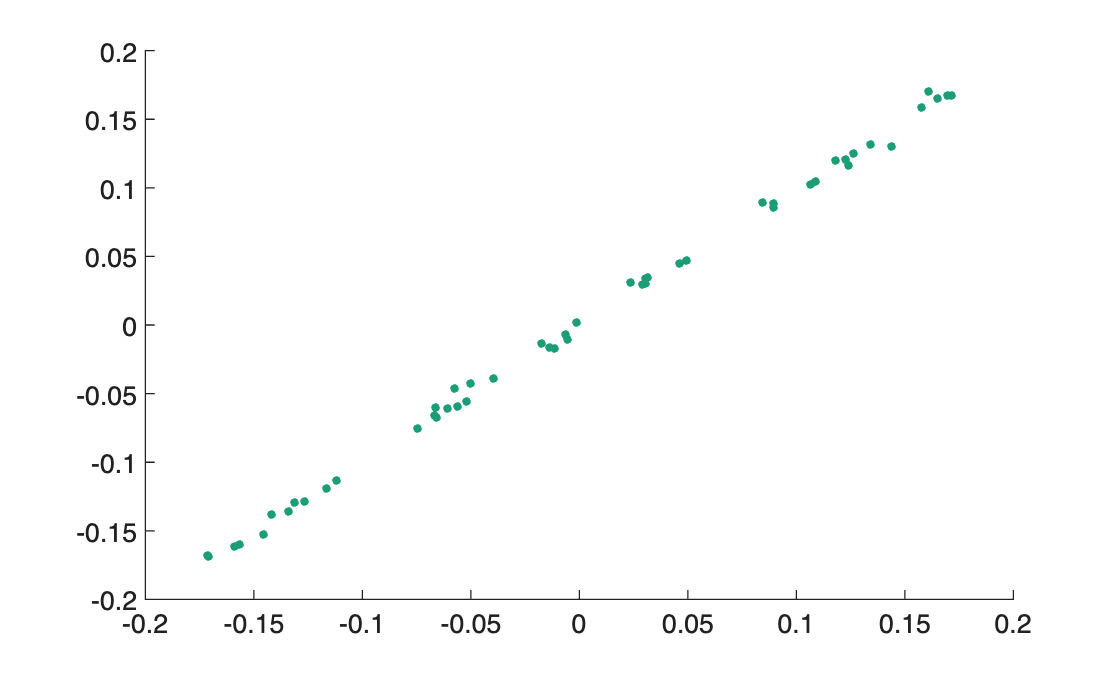

figure;
scatter(mod_FFX, beta_hat, 10, [27,158,119]./255, 'filled');